% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

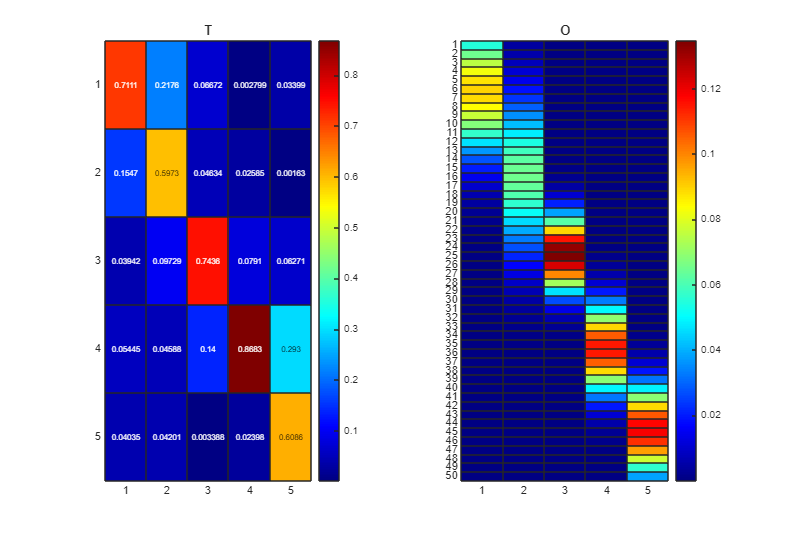

k = 5;
d = 50;
n = 1;

options.method = "random";
options.lambda = 5;

[T, O, Pi] = generateHMM(k, d, n, options);



figure('Renderer', 'painters', 'Position', [10 10 900 600])

subplot(1, 2, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(1, 2, 2);
h = heatmap(O, Colormap=jet());
h.Title = ['O'];

Generate an observational sequence based on the defined HMM

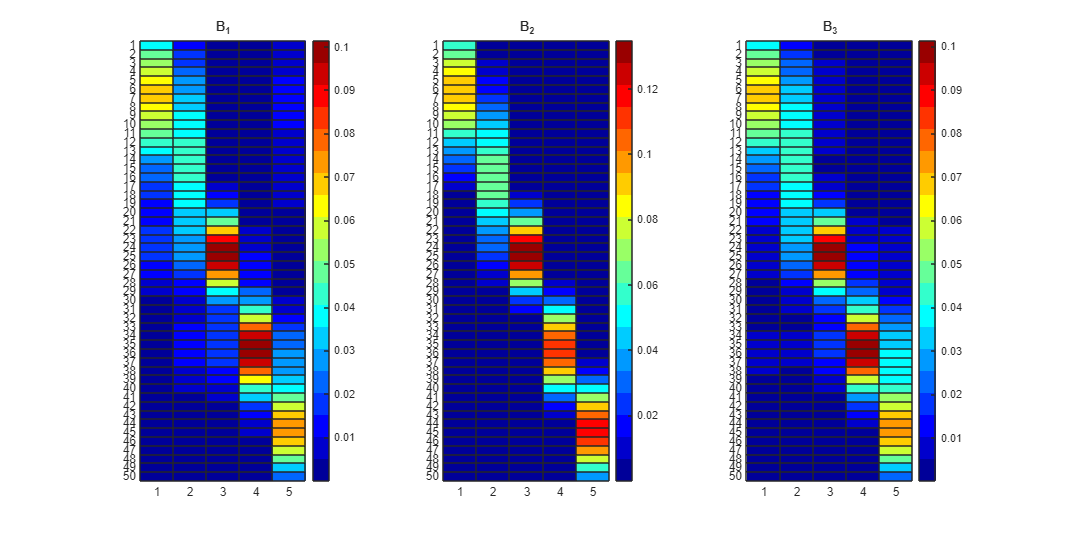

T_seq = 1e7;
P3 = zeros(d, d, d);

use_optimal_JPT = false;

if use_optimal_JPT
    for i = 1:n
        U = {};
        U{1} = Stochasticize(O * diag(Pi) * T' / inv(diag(T * Pi')));
        U{2} = O;
        U{3} = Stochasticize(O * T);
        P3 = cpdgen(U)/k;
    end
else
    [seq, states] = generate_hmm_sequence(T, O, Pi, T_seq);
    for i = 1:n
        P3 = ProbabilityTensorGenerate(seq(i, :), 3, d);
    end
end

PlotFactorMatrices({Stochasticize(O * diag(Pi) * T' / inv(diag(T * Pi'))), O, O*T})


O_hats = cell(n, 1);
T_hats = cell(n, 1);
T_hat = zeros(size(T));

epsilon = 1;
lambda = 5;

T_init = Stochasticize(lambda * eye(k) + epsilon * rand(k, k));
O_init = Stochasticize(lambda * ones(d, k) + epsilon * rand(d, k));

options.maxiter = 500;
options.th_relerr = 1e-6;
options.distIter = 0;
options.distribution = "Normal";


% [A, B, C, output] = cpd_als_structured(P3, k, T_init, O_init, options);
[A, B, C, ~, output] = cpd_als_3d(P3, k, options);


[T_hat, O_hat, pi_hat] = FactorMatrices2HMM({A, B, C});
[T_hat, O_hat, pi_hat, Pbest] = remove_hmm_permutation_emission(O, T_hat, O_hat, pi_hat);

[eig(T), eig(T_hat)]

ans =     1.0000    1.0000
    0.4647    0.4671
    0.8078    0.8088
    0.5748    0.5762
    0.6815    0.6833


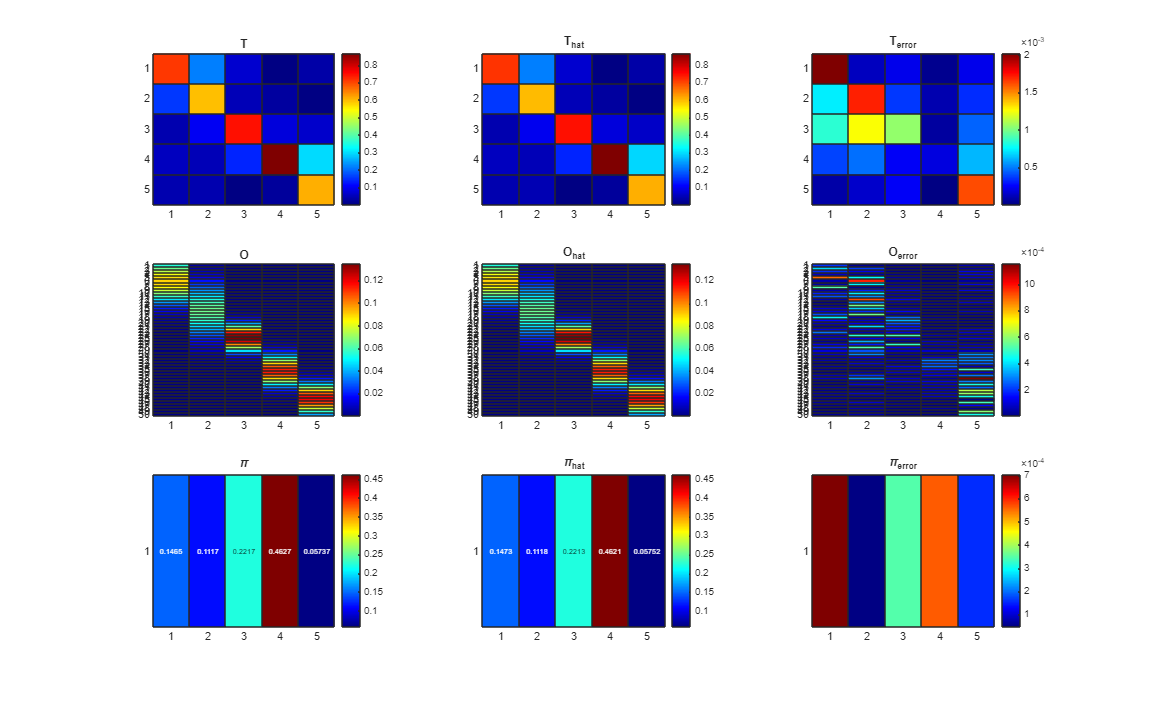


plotHMMError(T, T_hat, O, O_hat, Pi, pi_hat);

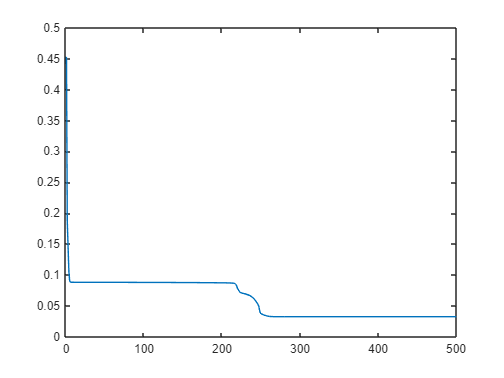



figure()
plot(output.relerr)

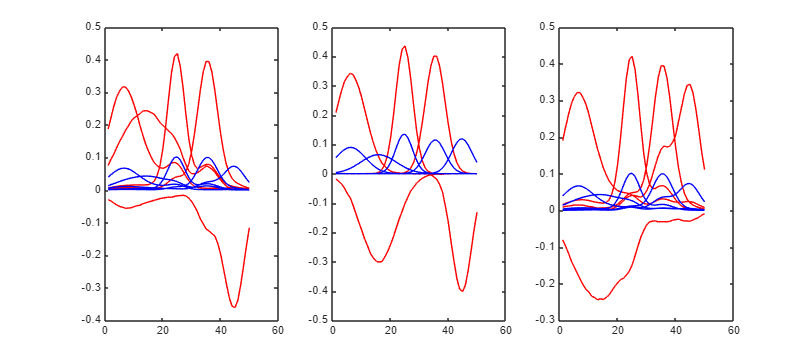

figure('Renderer', 'painters', 'Position', [10 10 900 400])
subplot(1, 3, 1);
plot(A, "r"); hold on; plot(Stochasticize(O * diag(Pi) * T' / inv(diag(T * Pi'))), 'b');

subplot(1, 3, 2);
plot(B, "r"); hold on; plot(O, 'b');

subplot(1, 3, 3);
plot(C, "r"); hold on; plot(O*T, 'b');

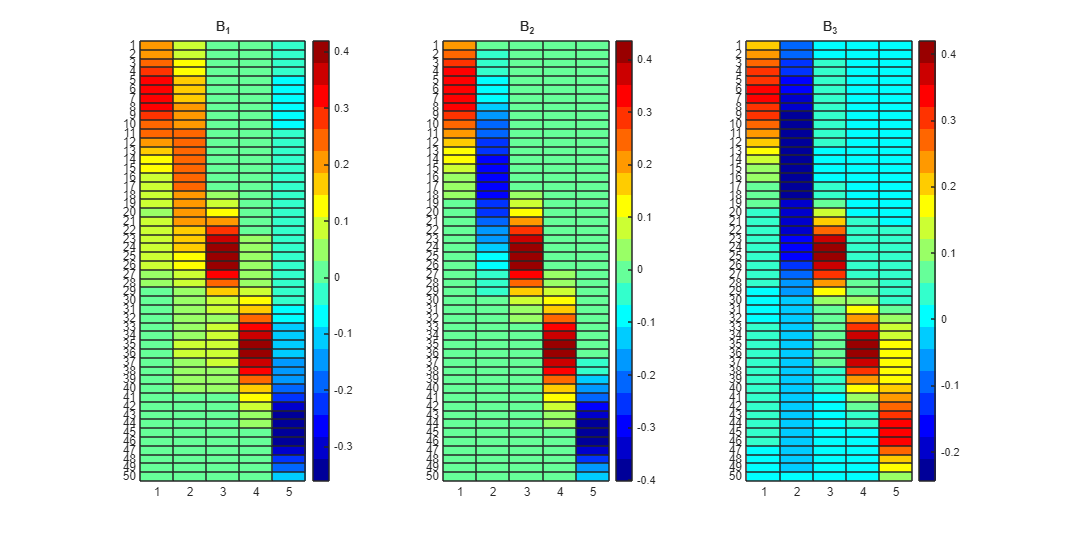


PlotFactorMatrices({A * Pbest', B * Pbest', C * Pbest'})


PlotFactorMatrices({Stochasticize(O * diag(Pi) * T' / inv(diag(T * Pi'))), O, O*T})